% Loading raw pitch angle data
load('G:\My Drive\Research\Projects\Collaborations\Yiqun Yu\Data\pitchAngleDistribution20080326.mat');

% Loading processed loss cone data
load('G:\My Drive\Research\Projects\Collaborations\Yiqun Yu\Data\Final\TS96\lossConeFluxTHMADE_20080326_TS96_with_footpoints.mat');


% Loading PFISR Energy
h5FilePath = 'G:\My Drive\Research\Projects\Data\20080326.001_bc_15sec-full_v1.h5';


pfisr.energyFlux = mean(h5read(h5FilePath, '/energyFluxFromMaxEnt/energyFlux'),2).*10^-4.*4*pi*(sind(180./2)).^2;
pfisr.energyBin = h5read(h5FilePath, '/energyFluxFromMaxEnt/energyBin');
pfisr.time = h5read(h5FilePath,'/energyFluxFromMaxEnt/time');


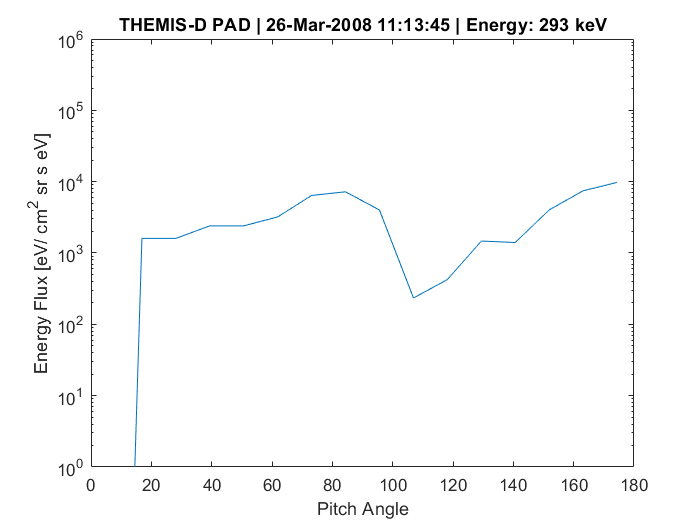

timeStr = '26 Mar 2008 11:13';
energyVal = 300*1000;

pfisr.timeIndex = find_time(pfisr.time,timeStr);
pfisr.energyIndex = find_altitude(pfisr.energyBin,energyVal);

timeIndex = find_time(dataPAD.thd.sst.time,timeStr);
energyIndex1 = find_altitude(dataPAD.thd.sst.energyBin,energyVal);

figure; 
semilogy(dataPAD.thd.sst.pa,squeeze(dataPAD.thd.sst.paFlux(timeIndex,energyIndex1,:)));
xlabel('Pitch Angle');
ylabel('Energy Flux [eV/ cm^2 sr s eV]')
title(['THEMIS-D PAD | ',datestr(dataPAD.thd.sst.time(timeIndex)),' | Energy: ',num2str(dataPAD.thd.sst.energyBin(energyIndex1)/1000),' keV']);
ylim([1,10^6]);

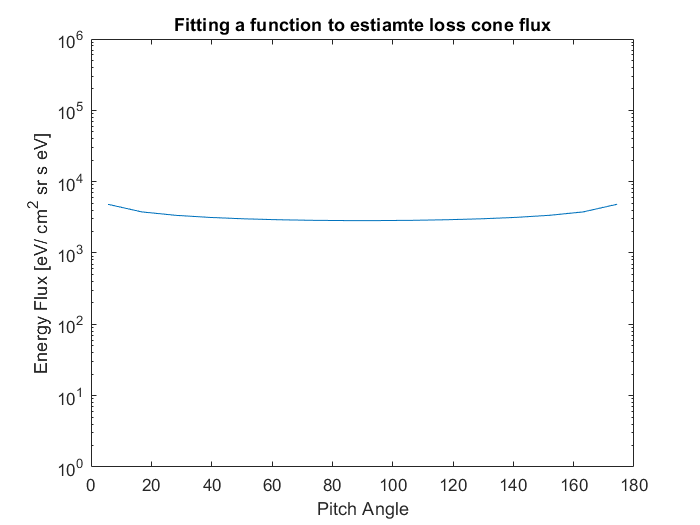


timeIndex = find_time(padData.thd.time,timeStr);
energyIndex = find_altitude(padData.thd.energyBin,energyVal);

fun = padData.thd.pitchAngleDistributionFunctionYi;

figure;
semilogy(padData.thd.pitchAngle,fun(padData.thd.fitYi.x0(timeIndex,energyIndex,:),padData.thd.pitchAngle));
xlabel('Pitch Angle');
ylabel('Energy Flux [eV/ cm^2 sr s eV]')
title('Fitting a function to estiamte loss cone flux');
ylim([1,10^6]);


padData.thd.trappedDiffEfluxYi = trapz(convert_deg_to_sr(padData.thd.pitchAngle),squeeze(dataPAD.thd.sst.paFlux(timeIndex,energyIndex1,:))); %fun(padData.thd.fitYi.x0(timeIndex,energyIndex,:),padData.thd.pitchAngle)

disp([datestr(dataPAD.thd.sst.time(timeIndex)),' | Energy: ',num2str(dataPAD.thd.sst.energyBin(energyIndex1)/1000),' keV'])

26-Mar-2008 11:12:09 | Energy: 293 keV



disp(['Loss cone flux from THEMIS = ',num2str(padData.thd.lcDiffEfluxYi(timeIndex,energyIndex)),' eV/ cm^2 s eV']);

Loss cone flux from THEMIS = 7250.4528 eV/ cm^2 s eV


disp(['Total flux from PFISR      = ',num2str(pfisr.energyFlux(pfisr.energyIndex,1,pfisr.timeIndex)),' eV/ cm^2 s eV']);

Total flux from PFISR      = 13044.1951 eV/ cm^2 s eV


disp(['Total flux                 = ',num2str(padData.thd.trappedDiffEfluxYi),' eV/ cm^2 s eV']);

Total flux                 = 15565.1781 eV/ cm^2 s eV


disp(' ')

disp('Loss cone flux divided by the total flux:')

Loss cone flux divided by the total flux:


disp(['THEMIS loss cone flux / THEMIS total flux = ', num2str(padData.thd.lcDiffEfluxYi(timeIndex,energyIndex)./(100*padData.thd.trappedDiffEfluxYi)),' %']);

THEMIS loss cone flux / THEMIS total flux = 0.0046581 %


disp(['PFISR flux / THEMIS total flux            = ', num2str(pfisr.energyFlux(pfisr.energyIndex,1,pfisr.timeIndex)./(100*padData.thd.trappedDiffEfluxYi)),' %']);

PFISR flux / THEMIS total flux            = 0.0083804 %


function [lossConeEnergyFlux,y,MSE] = get_loss_cone_flux(padFun,x0,pa,padData,lcArray,options)
    [y, resnormy] = lsqcurvefit(padFun,x0,pa,padData,[],[],options);
    MSE = resnormy/(length(pa)-2);
    padFunNew = @(x) padFun(y,x);
%     lax=linspace(0,la,50);
    lossConeEnergyFlux = trapz(convert_deg_to_sr(lcArray),padFunNew(lcArray)); %[eV/cm2 s eV]
%     lossConeEnergyFlux = integral(padFunNew,0,la); %eV/cm2 s eV
end


function sr = convert_deg_to_sr(angle)
    sr = 4*pi*(sind(angle./2)).^2;
end
